clear;
figure('Name',"All Regions",'NumberTitle','off');
fileNames = ["data/c3x7_s1602_l48.m","data/c3x7_s1794_l290.m","data/c3x7_s1914_l275.m","data/c7x17_s1602_l48.m","data/c7x17_s1794_l290.m","data/c7x17_s1914_l275.m"];
t = tiledlayout(2,3);
t.TileSpacing = 'tight';
t.Padding = 'tight';
regions = [1, 2, 3, 1, 2, 3];
cmap = colororder;
for l = 1:6
    boundary_N = 60;
    fileName = fileNames(l);
    
    N = 2000;

    %Samples = BruteForce(fileName, N);
    Pauli = PauliBasesPoints(fileName);
    CoherencePoints = MagnitudeDiversityFunc(fileName);
    boundary_vals = BoundaryScan(fileName, boundary_N);
    temp = [boundary_vals(:, 1); boundary_vals(:, 2)];
    P = linortfit(real(CoherencePoints), imag(CoherencePoints));
    groundPoint = findGround(P, Pauli);

    nexttile;
    hold on; axis equal; grid on;

    % ----- Plot -----

    scatter(real(groundPoint(1)), groundPoint(2), 35, ...
            'MarkerFaceColor', [1 0.647 0], ...
            'MarkerEdgeColor', [1 0.647 0], 'LineWidth',1.2);

    scatter(real(boundary_vals(:,1)), imag(boundary_vals(:,1)), 12, ...
            'MarkerEdgeColor', 'red', 'MarkerFaceColor','none');
    scatter(real(boundary_vals(:,2)), imag(boundary_vals(:,2)), 12, ...
            'MarkerEdgeColor', 'red', 'MarkerFaceColor','none');
    
    scatter(real(CoherencePoints), imag(CoherencePoints), 16, 'filled', ...
            'MarkerFaceColor', cmap(1,:), ...
            'MarkerEdgeColor', cmap(1, :));

    % line fit
    x = linspace(-1, 1, 200);
    plot(x, P(1)+P(2)*x,'black'  ,'LineWidth',1.6);

    % unit circle
    th = linspace(0,2*pi,300);
    plot(cos(th), sin(th), 'k--');

    % fixed axis limits
    xlim([-1 1]);
    ylim([-1 1]);
    [~, base, ~] = fileparts(fileName);  % base = 'c3x7_s1602_l48'
    tokens = regexp(base, 'c(\d{1})x(\d{1,2})', 'tokens', 'once');
    
    title(sprintf('Region %d (%dx%d)', regions(l), str2double(tokens{1}), str2double(tokens{2})) );
end


% xlim([-1 1]);
% ylim([-1 1]);

%legend('Location','eastoutside');
hold off;


% ======== EXPORT TO PDF ========


set(gcf, 'Units', 'centimeters');        % use actual physical units
outerpos = get(gca, 'OuterPosition');
ti = get(gca, 'TightInset');
set(gca, 'Position', [outerpos(1)+ti(1), outerpos(2)+ti(2), ...
                      outerpos(3)-ti(1)-ti(3), outerpos(4)-ti(2)-ti(4)]);

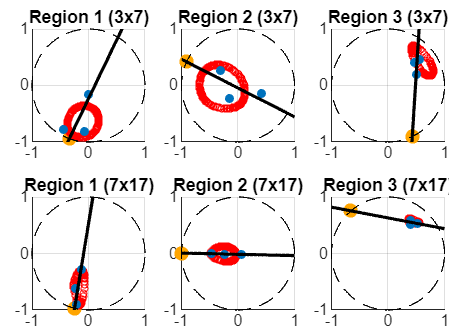

%set(gcf, 'Position', [2 2 20 20]);       % width x height (cm) for the PDF

figPos = get(gcf, 'Position');     % [x y width height]
figWidth  = figPos(3);
figHeight = figPos(4);

set(gcf, 'PaperUnits', 'centimeters');
set(gcf, 'PaperSize', [figWidth figHeight]);
set(gcf, 'PaperPositionMode', 'manual');
set(gcf, 'PaperPosition', [0 0 figWidth figHeight]);

print(gcf, 'MagnitudeDiversity.pdf', '-dpdf', '-r300');  % high-quality vector PDF